# DC motor postion control: PID

## Design Criteria

- Settling time less than 0.040 seconds

- Overshoot less than 16%

- No steady-state error, even in the presence of a step disturbance input

## Open loop transfer function

J = 3.2284E-6;
b = 3.5077E-6;
K = 0.0274;
R = 4;
L = 2.75E-6;
s = tf('s');
sys = K/(s*((J*s+b)*(L*s+R)+K^2));

## Propotional control

In order to see the effect of proportional control, we increase the gain from 1 to 21 with the following code

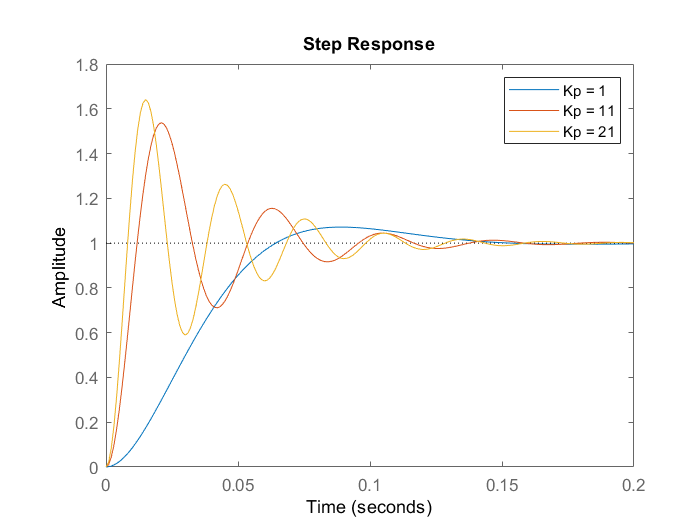

kp = 1;
for i = 1:3
    C(:, :, i) = pid(kp);
    kp = kp +10;
end
sys_cl=feedback(C*sys, 1);
t = 0:0.001:0.2;
step(sys_cl(:,:,1), sys_cl(:,:,2), sys_cl(:,:,3), t);
legend('Kp = 1',  'Kp = 11',  'Kp = 21');

Now, we see its response to the disturbance

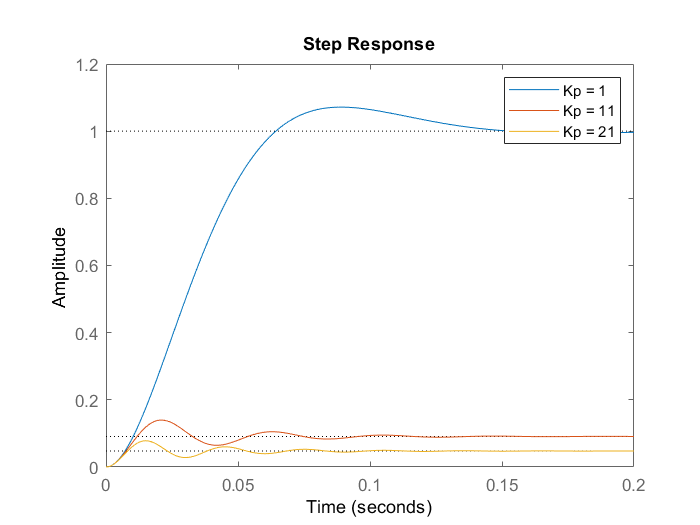

dist_cl = feedback(sys, C);
t = 0:0.001:0.2;
step(dist_cl(:,:,1), dist_cl(:,:,2), dist_cl(:,:,3), t);
legend('Kp = 1',  'Kp = 11',  'Kp = 21');

This indicates that we need to get a PI controller to get rid of the error from the disturbance

## PI controller

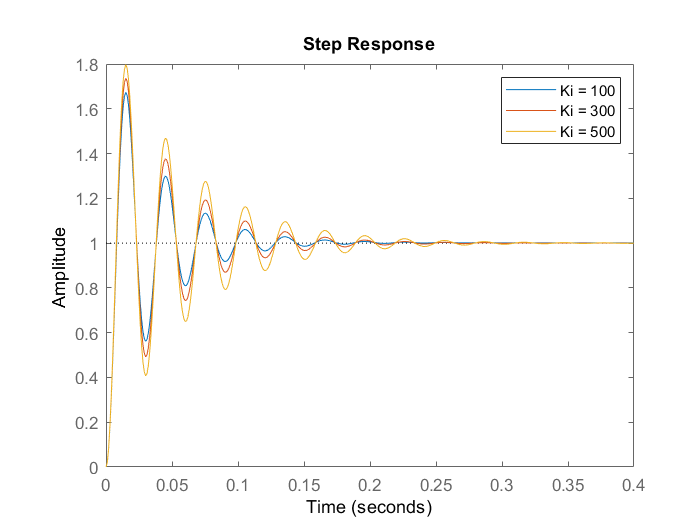

Kp = 21;
Ki = 100;
for i = 1:5
    C(:,:,i) = pid(Kp,Ki);
    Ki = Ki + 200;
end

sys_cl = feedback(C*sys,1);
t = 0:0.001:0.4;
step(sys_cl(:,:,1), sys_cl(:,:,2), sys_cl(:,:,3), t);
legend('Ki = 100', 'Ki = 300', 'Ki = 500');

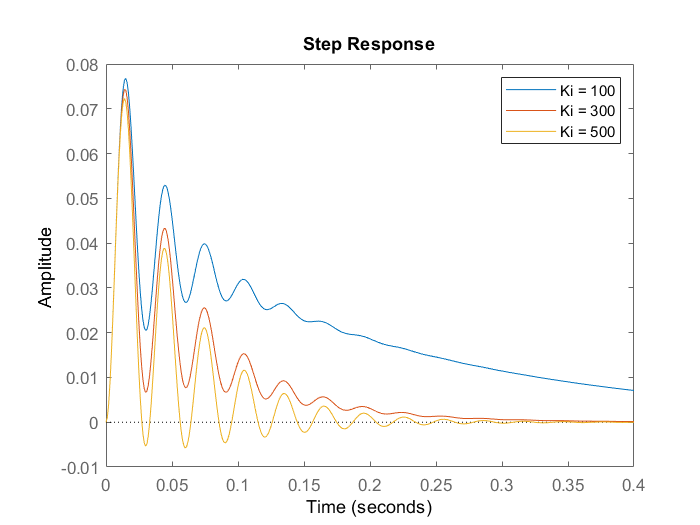

dist_cl = feedback(sys, C);
step(dist_cl(:, :, 1), dist_cl(:, :, 2), dist_cl(:, :, 3), t);
legend('Ki = 100', 'Ki = 300', 'Ki = 500');

## PID control

We pick kp =21, ki = 500, then range kd from  0.05 to 0.25

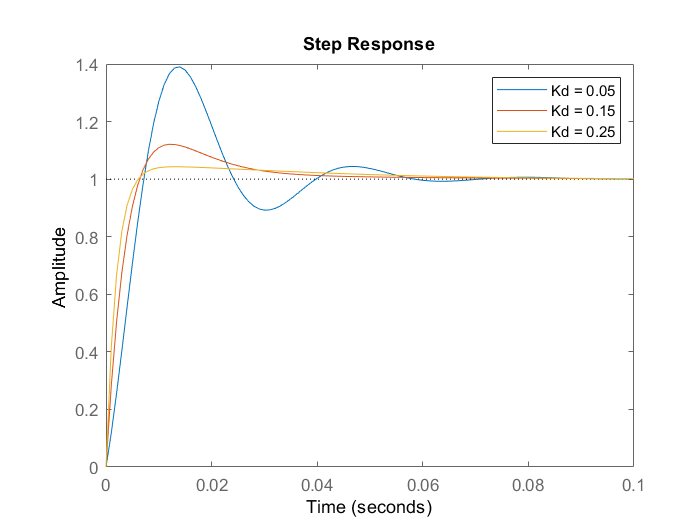

Kp = 21;
Ki = 500;
Kd = 0.05;

for i = 1:3
    C(:,:,i) = pid(Kp,Ki,Kd);
    Kd = Kd + 0.1;
end

sys_cl = feedback(C*sys,1);
t = 0:0.001:0.1;
step(sys_cl(:,:,1), sys_cl(:,:,2), sys_cl(:,:,3), t);
legend('Kd = 0.05', 'Kd = 0.15', 'Kd = 0.25')

Use the command stepinfo to see the design result

stepinfo(sys_cl(:,:, 2))

ans = struct with fields:
        RiseTime: 0.0046
    SettlingTime: 0.0338
     SettlingMin: 0.9103
     SettlingMax: 1.1212
       Overshoot: 12.1175
      Undershoot: 0
            Peak: 1.1212
        PeakTime: 0.0122
